## Checking the discrete-time system

We start by loading the experimental data and the transfer function we determined with this experimental data in the previous step.  

clear all;
close all;
load("../../step003-identify-transfer-function/matlab/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
tData= identifyTransferFunctionContinuousTimeResults.tData;
yDeg= identifyTransferFunctionContinuousTimeResults.yData;

Let"s plot the open-loop transfer function again for completeness. Recall the transfer function has the form

 
$$\[
G_S(s)= \frac{K_S}{s^2+ a_1 s+ a_0}
\]$$


The corresponding differential equation reads

$\varphi^¨ +a_1 \varphi^˙ +\varphi =K_S u$.

We can read the gain $K_S$ and coefficients $a_1$ and $a_0$ off the transfer function found from the experimental data:

GS= identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction;
GS

GS =
 
  From input "u1" to output "y1":
          9448
  --------------------
  s^2 + 33.26 s + 8641
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using TFEST on time domain data "identData".
Fit to estimation data: 88.02%                        
FPE: 0.02168, MSE: 0.01963                            


As a final preparation, we plot the step response to visually check that we are treating the expected transfer function.

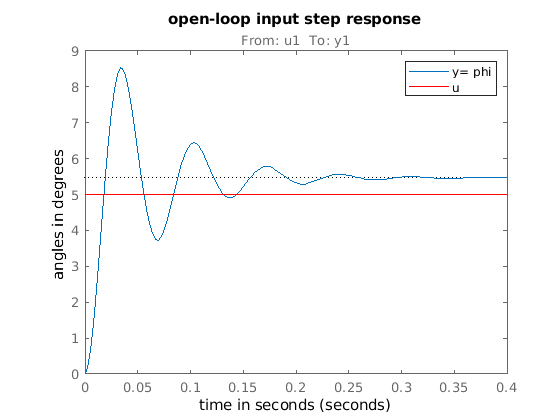

figure();
stepOpt = stepDataOptions('StepAmplitude', uStep);
step(GS, stepOpt); 
hold on;
uData= uStep* ones(1, length(tData)); 
plot(tData, uData, '-', 'Color', 'red'); 
legend("y= phi", "u"); 
xlabel("time in seconds"); 
ylabel("angles in degrees"); 
title("open-loop input step response");
hold off; 

## Closed-loop with PID controller

### Transfer function of the closed loop

We treat the following closed loop. The lecture notes for the lab explain this system and the calculations summarized here in more detail.

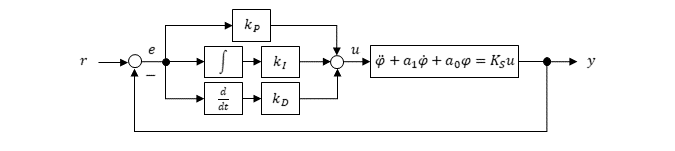

The corresponding differential equation reads as follows. Make sure you recognize all blocks of the PID controller in the block diagram and in the differential equation. 


$$\varphi^¨ +a_1 \varphi^˙ +a_0 \varphi =K_S \left(k_P \left(r-\varphi \right)+k_I \int_0^t \left(r\left(\tau \;\right)-\varphi \left(\tau \;\right)\right)d\tau \;+k_D \frac{d}{\textrm{dt}}\left(r\left(t\right)-\varphi \left(t\right)\right)\right)$$


It is convenient to treat this system in the frequency space. Recall the output is $y=\varphi$ and $Y$ is its Laplace-transform. The transfer function $G_S=\frac{K_S}{s^2+ a_1 s+ a0}$ of the second order differential equation $\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= K_Su$ was already stated above.

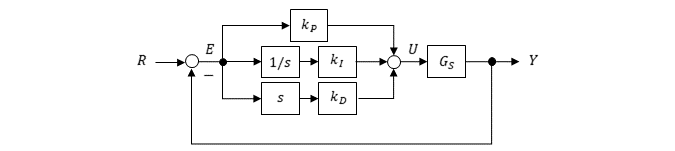

Laplace-transforming the differential equation of the block diagram yields

$s^2 Y+a_1 \textrm{sY}+a_0 Y=K_S \left(k_P +\frac{k_I }{s}+sk_D \right)\left(R-Y\right)$.

Multiplying both sides by $s$ and rearranging terms then yields the closed-loop transfer function 

$G_{cl}=\frac{Y}{R}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}$.

### Pole placement: Idea and equations

Recall that "pole placement" refers to the following idea: The poles of $G_{cl}$ determine the stability of the closed loop. Moreover, the real parts of the poles determine how fast the system converges to a steady state, and the imaginary parts determine the frequencies of oscillations. We therefore would like to state desired poles (3 poles, because the denominator of $G_{cl}$ is a thrid order polynomial) and find out how to set our three free controller parameters $k_P$, $k_I$, $k_D$ to achieve these poles. 

More technically, we would like to choose three poles $s_1$, $s_2$, $s_3$ (e.g., $s_1= -100$, $s_2=-101$, $s_3= -102$ for stability, fast decay and no oscillations) and choose $k_P$, $k_I$, $k_D$ such that

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}=K_S\frac{k_Ds^2+k_Ps+k_I}{(s-s_1)(s-s_2)(s-s_3)}$.

This equality obviously holds it the denominators are equal, i.e.,

$s^3+(a_1+K_S k_D)s^2+ (a_0+K_S k_P)s+K_S k_I= (s-s_1)(s-s_2)(s-s_3)$.

Expanding the right hand side yields


$$s^3+(a_1+K_S k_D)s^2+ (a_0+K_S k_P)s+K_S k_I= s^3 + (-s_1 - s_2 - s_3) s^2 + (s_1 s_2 + s_1 s_3 + s_2 s_3) s - s_1 s_2 s_3$$


and by comparing coefficients we find

$a_1+ K_S k_D= -s_1-s_2-s_3$, 

$a_0+K_S k_P=s_1 s_2+ s_1 s_3+ s_2 s_3$, 

$K_S k_I= -s_1 s_2 s_3$.

These equations can be solved for $k_P$, $k_I$, $k_D$. This yields

$k_P = -(-s_1 s_2 - s_1 s_3 - s_2 s_3 + a_0)/K_S$,

$k_D = -(a_1 + s_1 + s_2 + s_3)/K_S$,

$k_I = -s_1 s_2 s_3/K_S$.

### Pole placement: Application to our example

We first need to extract the coefficients $a_0$, $a_1$, $a_2$ and $K_S$ from our open-loop transfer function. 

G= identifyTransferFunctionContinuousTimeResults.continuousTimeTransferFunction;
K= G.Numerator;
a2= G.Denominator(1); 
a1= G.Denominator(2);
a0= G.Denominator(3);
if(a2~=1) 
    error("expecting a2= 1");
end

We choose the desired poles in the next step:

continuousTimePoles= [-101, -100, -102];
s1= continuousTimePoles(1);
s2= continuousTimePoles(2);
s3= continuousTimePoles(3);

Now we are ready to evaluate pole placement equations derived above. 

kP= -(-s1 * s2 - s1 * s3 - s2 * s3 + a0) / K;
kD= -(a1 + s1 + s2 + s3) / K;
kI= -s1 * s2 * s3 / K;

Create controller transfer function and step response for Gu=Go/(1+Go): 

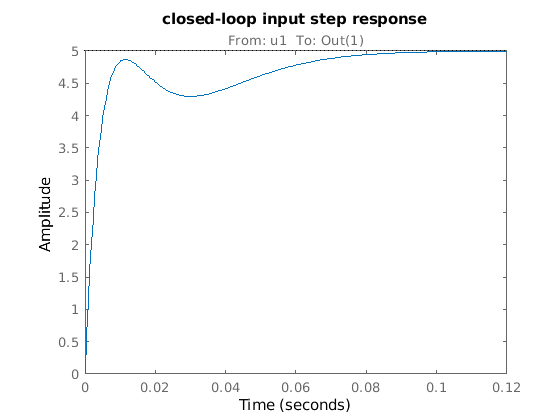

GR= tf([kD, kP, kI], [1, 0]);
Gu= feedback(GR* G, 1);
stepOpt = stepDataOptions('StepAmplitude', uStep);
step(Gu, stepOpt); 
title("closed-loop input step response");

The system reaches the new steady state in about 1/10 of a second. It does not oscillate (for an oscillation it would have to swing to values larger than 5 degrees), but it wiggles. The disturbance rejection also suffers from the wiggling motion:

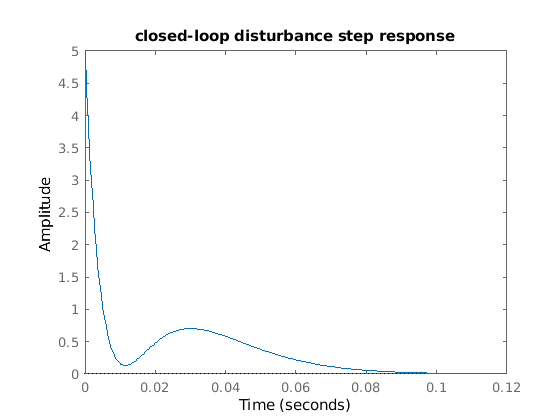

step(1/(1+GR* G), stepOpt)
title("closed-loop disturbance step response");

## Closed loop with smoother (but slower) PID controller

### Idea

We expect the step response of a third order transfer function

$G_{\mathrm{helper}}=\frac{K_\textrm{helper}}{(s-s_1)(s-s_2)(s-s_3)}$.

for three real poles, e.g. $s_1= -100$, $s_2= -101$, $s_3= -102$ not to have the wiggling behaviour found in the pole placement result for the PID controller above. We would expect this, because $G_\textrm{helper}$ can be understood to result from a series connection of three first order transfer functions, i.e.

$G_\textrm{helper}= K_\textrm{helper}\frac{1}{s-s_1} \cdot \frac{1}{s-s_2} \cdot \frac{1}{s-s_3}$.

Let's check the step response of $G_\textrm{helper}$ by plotting it to check. Expanding the transfer function $G_{\mathrm{helper}}$ yields

$G_{\mathrm{helper}}= \frac{K_\textrm{helper}}{(s-s_1)(s-s_2)(s-s_3)}= \frac{K_\textrm{helper}}{s^3 + (-s_1 - s_2 - s_3) s^2 + (s_1 s_2 + s_1 s_3 + s_2 s_3) s - s_1 s_2 s_3}$.

The form on the right hand side is convenient for use with matlabs tf() command. The next code snippet plots the unit step response. (Note that we need to set $K_\textrm{helper}$ so that the steady-state gain of $G_\textrm{helper}$ is 1 because we want the unit step response to attain 1 for $t\rightarrow\infty$. This yields $K_\textrm{helper}= \lim_{s\rightarrow 0} G_\textrm{helper}(s)= -s_1 s_2 s_3$.)

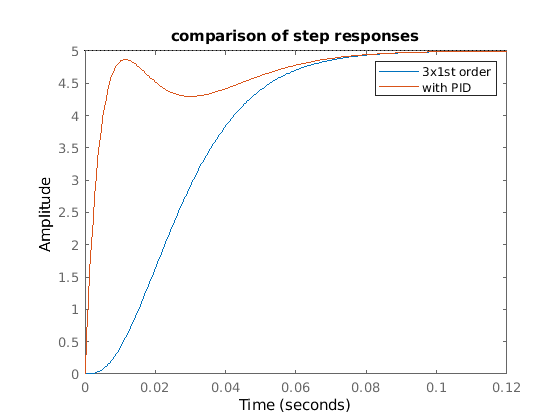

figure();
stepOpt = stepDataOptions('StepAmplitude', uStep);
step(tf(-s1*s2*s3, [1 -s1-s2-s3 s1*s2+s1*s3+s2*s3 -s1*s2*s3]), stepOpt)
hold on;
step(Gu, stepOpt); 
title("comparison of step responses"); 
legend("3x1st order", "with PID"); 

### Applying the idea to $G_\textrm{cl}$

Compare $G_\textrm{helper}$ to $G_\textrm{cl}$, where $G_\textrm{cl}$ is copied from above:

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{(s-s_1)(s-s_2)(s-s_3)}, \quad G_{\mathrm{helper}}=\frac{K_\textrm{helper}}{(s-s_1)(s-s_2)(s-s_3)}$.

A closed-loop transfer function of the form of $G_\textrm{helper}$ would obviously result, if we managed to remove the contributions $k_Ds^2$ and $k_P s$ from the numerator of $G_\textrm{cl}$. Setting $k_D$ and $k_P$ to zero would not provide the desired result, because $k_D$ and $k_P$ also enter the numerator of $G_\textrm{cl}$. This is evident from the equation

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}=K_S\frac{k_Ds^2+k_Ps+k_I}{(s-s_1)(s-s_2)(s-s_3)}$,

which is taken from the section on pole placement above and repeated here for convenience. We can, however, adjust the control loop to keep the desired numerator  and thus the desired poles


$$\frac{1}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}=\frac{1}{(s-s_1)(s-s_2)(s-s_3)}$$


but remove $k_D s^2$ and $k_P s$ from the numerator, i.e. achieve the replacement

$K_S\cdot(k_D s^2+ k_P s+ k_I)\longrightarrow K_S k_I$. In other words, we would like to achieve the replacment

$G_\textrm{cl}=K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}\longrightarrow K_S\frac{k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}= G_{\textrm{cl, new}}$.

It is easy to see how this replacement can be achieved by analysing the differential equation with the PID controller stated above which is repeated here for conveneicne. It reads


$$\varphi^¨ +a_1 \varphi^˙ +a_0 \varphi =K_S \left(k_P \left(r-\varphi \right)+k_I \int_0^t \left(r\left(\tau \;\right)-\varphi \left(\tau \;\right)\right)d\tau \;+k_D \frac{d}{\textrm{dt}}\left(r\left(t\right)-\varphi \left(t\right)\right)\right)\ldotp$$


We first recall how this differential equation corresponds to $G_\mathrm{cl}$ (**step 1**). It is then easy to see how the differential equation must be altered to correspond to $G_\mathrm{cl, new}$ (**step 2**). Finally, we will see that the altered differential equation corresponds to a new closed-loop block diagram (**step 3**).

#### Step 1 

We first differentiate the differential equation to remove the integral. This yields

$\dddot{\varphi}+ a_1\ddot{\varphi}+ a_0 \dot{\varphi}= K_S\left(k_P (\dot{r}- \dot{\varphi})+ k_I(r-\varphi)+ k_D (\ddot{r}- \ddot{\varphi})\right)$.

By collecting terms we obtain


$$\dddot{\varphi}+ (a_1+ K_S k_D)\ddot{\varphi}+ (a_0+K_S k_P) \dot{\varphi}+ K_S k_I \varphi= K_S\left(k_P \dot{r}+ k_I r+ k_D \ddot{r}\right)$$


and Laplace transforming with $y=\varphi$ and assuming zero initial conditions yields


$$s^3 Y+ (a_1+ K_S k_D)s^2 Y+ (a_0 K_S k_P) s Y+ K_S k_I Y= K_S k_D s^2 R+ K_S k_P s R+ K_S k_I R$$


or equivalently 

$\frac{Y}{R}= K_S\frac{k_Ds^2+k_Ps+k_I}{s^3+(a_1+K_S k_D)s^2+(a_0+K_S k_P)s+ K_S k_I}$,

which is $G_\mathrm{cl}$.

#### Step 2

By going throuth the manipulations of step 1 backwards we see that removing $k_D s^2+ k_P s$ from the numerator of $G_\mathrm{cl}$ (but not altering anything else about $G_\mathrm{cl}$ is equivalent to replacing the right hand side of the differential equation by 


$$\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= K_S\left(k_P(r-\varphi)+ k_I\int_0^t (r(\tau)- \varphi(\tau)d\tau+ k_D \frac{d}{dt} (r(t)- \varphi(t))\right)\longrightarrow\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= K_S\left(k_P(-\varphi)+ k_I\int_0^t (r(\tau)- \varphi(\tau)d\tau+ k_D \frac{d}{dt} (- \varphi(t))\right).$$


Note that this means the proportial and differential terms apply to $\varphi$ (more precisely, to $-\varphi$) instead of to $r-\varphi$. The integral term, in contrast, still applies to $r-\varphi$. 

#### Step 3

Let us rewrite the differential equation with the new right hand side for convenience to read 


$$\ddot{\varphi}+ a_1\dot{\varphi}+ a_0\varphi= \underbrace{k_I\int_0^t (r(\tau)- \varphi(\tau)d\tau}_{=:\bar{u}}- \underbrace{\left(K_S k_P\,\varphi+ K_S k_D \frac{d}{dt} \varphi(t)\right)}_{=:\tilde{u}}.$$


 We can generate $\tilde{u}$ by applying the proportional and differential terms to $\varphi$ before the subtraction symbol that yields $r-\varphi$:

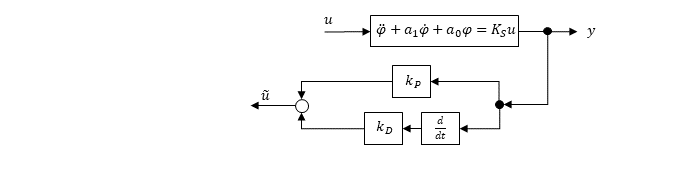

The signal $\bar{u}$ can be generated as before:

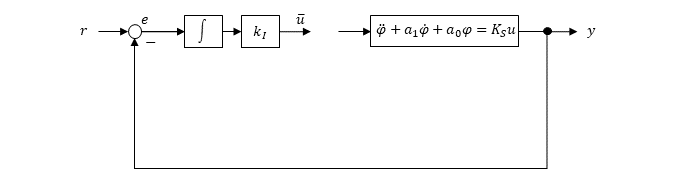

Combining $\bar{u}$ and $\tilde{u}$, taking the sign in front of $\tilde{u}$ into account, yields the new closed loop: